
%  delete(gcp('nocreate'))
%  parpool ('local',12)
% 
% pic_x=zeros(1,7);
% pic_y=zeros(1,7);
% for bit_length=1:1:7
%     pic_x(bit_length)=1000*bit_length;
%     for repeat=1:1:20
%         try
%         tic
%         pic_x(bit_length);
%         repeat

% tic
% profile on
%%初始环境参数
 d_initial=5.*10.^(-4);
 V=5*10^(-4);
 M=3.*10.^(6);       
 D=1*10.^(-9);    
 Dr=5;                
v=1.975*10^(-4);
r=30*10^(-6);
%生成随机的bit位信息
%  for re=1:1:10   %%%%%%%%%%%%%%%%% 运行7次,然后求平均值

patch=10%%分块的个数

patch = 10

patch_length=9%%m每一块的长度

patch_length = 9

num=patch_length*patch%%原始信息长度

num = 90

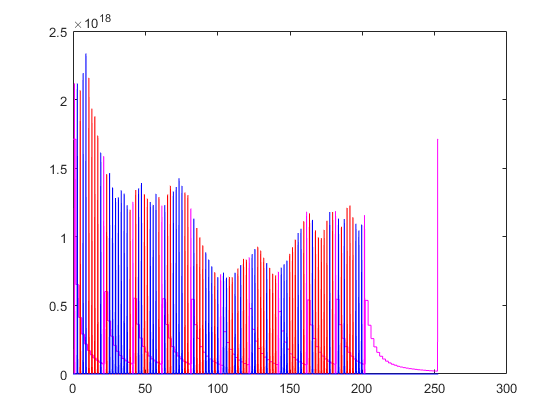

bit=rand(1,num);
bit(bit>0.5)=1;
bit(bit<=0.5)=2;
bit ; %%生成0~1随机数序列
B=encode_abc(bit,patch_length);%% 信息编码成三分子
encode_a_b_c=B;
%%【分别作出abc三种分子的编码】
encode_a=encode_a_b_c;
encode_b=encode_a_b_c;
encode_c=encode_a_b_c;
encode_a(encode_a~=1)=0 ;
encode_b(encode_b~=2)=0;
encode_b=encode_b/2;
encode_c(encode_c~=3)=0;
encode_c=encode_c/3;


%%【本实验可以进行边界一步碰撞折返】
% r=30*10^-6;
[x,y,z]=cylinder(r);%%【倒下的圆柱体】
h=1000;%%【圆柱长度】
z=z*h;
% mesh(z,y,x);%【mesh画出彩色网格图，surf画出表面着色图】
% xlim([-1,1]);
% ylim([-1,1]);
% zlim([-1,2]);
% alpha(0.5)%%【设置图像透明度】
% title('单位圆柱体');
% axis equal
% hold on 
%%三维移动性
example_time=0.02; %%%%%%%%%%%%%%%%%%%%%%%%%%%%
example_number=2./example_time; %% 每两秒钟的采样数
t1=0:example_time:2.5*length(encode_a_b_c)-example_time; %% 每一位2秒，再两倍时间长度，一共四倍
t2=0:example_time:25-example_time;  %%【注意，t2的大小可能会影响阈值设置】

%%【旋转游走距离变化】
theta_xy=zeros(size(t1));
theta_z=zeros(size(t1));
d_mobile=zeros(size(t1));
d_mobile(1)=0;
rotation_angle=rand(1,length(t1));
rotation_angle_xy=zeros(1,length(rotation_angle));
rotation_angle_z=zeros(1,length(rotation_angle));

%【控制三维的旋转角度】
%%【0.5概率x,y平面旋转】
for i=1:1:length(rotation_angle)
    if 0<rotation_angle(i) && rotation_angle(i)<0.025
       rotation_angle_z(i)=(2*Dr *example_time).^0.5;%【向z平面旋转】
    elseif 0.025<=rotation_angle(i) && rotation_angle(i)<0.05
       rotation_angle_z(i)=-(2 *Dr *example_time).^0.5;%【向z平面旋转】
    end
end

%【0.5概率z平面旋转】
for i=1:1:length(rotation_angle)
    if 0.05<rotation_angle(i) && rotation_angle(i)<0.075
       rotation_angle_z(i)=(2*Dr *example_time).^0.5;%【向z平面旋转】
    elseif 0.075<=rotation_angle(i) && rotation_angle(i)<0.1
       rotation_angle_z(i)=-(2 *Dr *example_time).^0.5;%【向z平面旋转】
    end
end
%【三维随机移动实验】
x=zeros(size(t1));
y=zeros(size(t1));
z=zeros(size(t1));
x(1)=d_initial;
y(1)=0;
z(1)=0;
d_mobile(1)=(x(1)^2+y(1)^2+z(1)^2)^0.5;
% plot3(x,y,z, '.b', 'markersize', 10);%绘制初始小球位置
% backColor = [1 1 1];set(gca, 'color', backColor);
% grid on;
% hold on

%%【运动分为无碰撞和有碰撞】【此处将运动修改为嵌套式，与步长时间example_time分开】
for i=2:1:length(theta_xy)-1
    theta_xy(i+1)=theta_xy(i)+rotation_angle_xy(i);%%【无碰撞中，下一步的方向角】
    theta_z(i+1)=theta_z(i)+rotation_angle_z(i);
    j=0.1*example_time;
    for q=1:1:10
        x(i)=x(i-1)+v*j*cos(theta_xy(i))*sin(theta_z(i));
        y(i)=y(i-1)+v*j*sin(theta_xy(i))*sin(theta_z(i));
        z(i)=z(i-1)+v*j*cos(theta_z(i));
        if r-(y(i)^2+z(i)^2)^0.5<=0.05*r %%【如果刚刚碰撞,则把（x,y,z）作为撞击点，进行向量化。入射向量b是"（···）"，对称轴是a"向量（x,y,z）-(x,0,0)"】
           b=[v*j*cos(theta_xy(i))*sin(theta_z(i)),v*j*sin(theta_xy(i))*sin(theta_z(i)),v*j*cos(theta_z(i))];
           a=[0,v*j*sin(theta_xy(i))*sin(theta_z(i)),v*j*cos(theta_z(i))];
           c=2*dot(b,a)/dot(a,a)*a-b;
           c=-c;%%调转方向%%【有碰撞中，下一步的方向角，但目前是向量显示】
           for e=q:1:10
               x(i)=x(i-1)+c(1);
               y(i)=y(i-1)+c(2);
               z(i)=z(i-1)+c(3);
           end
           %%【把向量转换为角度】
           z_danweixiangliang=[0,0,1];
           x_danweixiangliang=[1,0,0];
           chaji1=cross(z_danweixiangliang,c);
           sin_theta_z=(chaji1(1)^2+chaji1(2)^2+chaji1(3)^2)^0.5/(c(1)^2+c(2)^2+c(3)^2)^0.5;
           if sin_theta_z<0
              theta_z(i+1)=acos(dot(c,z_danweixiangliang)/(c(1)^2+c(2)^2+c(3)^2)^0.5)+180;
           end
           chaji2=cross(x_danweixiangliang,c);
           sin_theta_xy=(chaji2(1)^2+chaji2(2)^2+chaji2(3)^2)^0.5/(c(1)^2+c(2)^2+c(3)^2)^0.5;
           if sin_theta_xy<0
              theta_xy(i+1)=acos(dot(c,x_danweixiangliang)/(c(1)^2+c(2)^2+c(3)^2)^0.5)+180;
           end
          break
        end
    end
    d_mobile(i)=(x(i)^2+y(i)^2+z(i)^2)^0.5;
%        plot3(x,y,z, '.b', 'markersize', 10);%绘制实时小球位置
%        pause(0.01)
 end
d_mobile;


%%【计算A B C 浓度】

%%计算 c 码的浓度
c_total_c=zeros(size(t1));%% 10个比特，20秒钟，200个函数点 0-199;
c_total_c=concentration_calculate(c_total_c,encode_c,d_mobile,t1,M,D,V,example_number,d_initial);
values = spcrv([[t1(1) t1 t1(end)];[c_total_c(1) c_total_c c_total_c(end)]],3);
plot(values(1,:),values(2,:), 'm');
hold on
%【距离预测与阈值设置】
threshold=zeros(size(t1));
distance=zeros(size(t1));
detection_bit_total=zeros(size(t1));
count_c=0;
threshold(threshold>=0)=0.8*max(M./(4.*pi.*D.*t1).^(1.5).*exp(-(d_initial-V*t1).^2./(4.*D.*t1)));
for i=1:1:length(c_total_c)-1
    if c_total_c(i)<threshold(i)&&c_total_c(i+1)>=threshold(i+1)
        i;
       for k=i+1:1:length(c_total_c)-1
           if c_total_c(k)>=threshold(k)&&c_total_c(k+1)<threshold(k+1)%【k-i>10防止出现噪声的细小峰值的影响】
%               if k-i<5 
%                   break 
%               end
              k;
              count_c=count_c+1;%【计数第几个C分子，以此来计算传输时间】
              if count_c>=patch+2
                  break
              end
%              c_total_c(c_total_c(i+1+1:k-1)<threshold(i+1+1:k-1))=threshold(i)+1;%【防止出现噪声的细小峰值的影响，小峰挨着大峰会被检测出俩】
              [peak_concentration_c,index]=max(c_total_c(i+1:k));
              peak_position=i+index;
              detection_bit_total(peak_position)=3;%【求得峰值位置，在峰值位置上填3】
              [threshold,distance]=threshold_prediction(count_c,peak_position,threshold,distance,example_time,example_number,patch_length,v,V,t1,t2,D,M);%【计算峰值距离并预测阈值】
              break %%【跳出k的循环】
           end
       end
    end          
end
values = spcrv([[t1(1) t1 t1(end)];[threshold(1) threshold threshold(end)]],3);
plot(values(1,:),values(2,:), 'm');
hold on

%%【计算 a 码的浓度，并信号检测】
c_total_a=zeros(size(t1));%% 10个比特，20秒钟，200个函数点 0-199;
c_total_a=concentration_calculate(c_total_a,encode_a,d_mobile,t1,M,D,V,example_number,d_initial);
detection_bit_total=detection(detection_bit_total,c_total_a,threshold,1);
values = spcrv([[t1(1) t1 t1(end)];[c_total_a(1) c_total_a c_total_a(end)]],3);
plot(values(1,:),values(2,:), 'R');
hold on

%%【计算 b 码的浓度，并信号检测】
c_total_b=zeros(size(t1));%% 10个比特，20秒钟，200个函数点 0-199;
c_total_b=concentration_calculate(c_total_b,encode_b,d_mobile,t1,M,D,V,example_number,d_initial);
detection_bit_total=detection(detection_bit_total,c_total_b,threshold,2);
values = spcrv([[t1(1) t1 t1(end)];[c_total_b(1) c_total_b c_total_b(end)]],3);
plot(values(1,:),values(2,:), 'b');
hold on


%%把中间多余的0去掉
% detection_bit_total
index=find(detection_bit_total==0);
detection_bit_total(index)=[];
detection_bit_total

detection_bit_total =      3     2     1     2     2     1     1     1     1     2     3     1     2     2     2     2     2     2     2     1     3     1     2     2     1     1     2     2     2     1     3     2     1     1     2     2     2     2     1     1     3     2     1     1     1     2     2     2     1     2

for i=length(detection_bit_total):-1:1
    if detection_bit_total(i)~=3
       detection_bit_total(i)=[];
    else
        break
    end
end
detection_bit_total;
%%%添加中间缺少的位置%%多次循环，一次只循环一个代码段
for i=1:1:patch
    detection_bit_total=tianjia(detection_bit_total,patch_length);
end
detection_bit_total;
% decode_bit;
% %%%删除中间多余的位置 %%多次循环，一次只循环一个代码段
for i=1:1:patch
    detection_bit_total=shanchu(detection_bit_total,patch_length);
end
detection_bit_total;

error=zeros(size(encode_a_b_c));
duibi=[encode_a_b_c;detection_bit_total;error]; %%对比一下源码与解码
for i=1:1:length(encode_a_b_c)
    if duibi(1,i)~=duibi(2,i)
       duibi(3,i)=duibi(1,i);
    end
end
duibi;
BER=biterr(encode_a_b_c,detection_bit_total)./length(encode_a_b_c)

BER = 0



% ber_repeat(repeat)=BER
%     toc
%         catch
%         end
%     end
%     pic_y(bit_length)=mean(ber_repeat)%%【求平均值】
%     plot(pic_x,pic_y,'-<B','LineWidth',1);
%     hold on
% 
% end
% delete(gcp('nocreate'))






%%三种分子编码函数

function B=encode_abc(bit,patch_length)
    B = [3];
    n = length(bit); % 得到bit长度
    for i=1:n
      B=[B bit(i)];
        if mod(i,patch_length)==0
        B = [B 3];
        end
    end
%             if B(end)==3
%            B(end)=[];
%             end
end

%% 浓度计算引用的函数
function c_total=concentration_calculate(c_total,encode,d_mobile,t1,M,D,v_drift,example_number,d_initial)
    c_total=encode(1).*M./(4.*pi.*D.*(t1)).^(1.5).*exp(-(d_mobile-v_drift*t1).^2./(4.*D.*t1));
    for i=2:1:length(encode) %%遍历待发送比特
%     for i=2:1:length(encode) %%遍历待发送比特
        c_total=c_total+c_current(i,d_mobile,t1,M,D,v_drift,example_number,encode);
    end
    %% 使用平均值取消掉NAN数据
    c_total(1)=0;
    c_total(isnan(c_total)==1)=(c_total(find(isnan(c_total)==1)-1)+c_total(find(isnan(c_total)==1)+1))/2;
%     c_total((c_total<10^-10)==1)=0;
    %【加入噪声】
%      noise = awgn(c_total,snr,'measured'); 
%      c_total=c_total+noise;%加入信噪比为10db的噪声，加入前预估信号的功率（强度）
%   %【噪声？】 
% %%%%%%%%%????????????
%        noise= normrnd(0,(c_total*(10^18)).^0.5);
%        c_total=c_total+noise;

end

%% 浓度计算函数
function c_bit=c_current(i,d_mobile,t1,M,D,v_drift,example_number,encode)
    c_bit=zeros(size(t1));    
%       for j=(i-1)*example_number+1:1:(i-1)*example_number+3*example_number%%【压缩最大值会出bug】
    for j=(i-1)*example_number+1:1:length(c_bit)%%
        k=j-example_number*(i-1);
        c_bit(j)=encode(i).*M./(4.*pi.*D.*(t1(k))).^(1.5).*exp(-(d_mobile(j)-v_drift*t1(k)).^2./(4.*D.*t1(k)));
        %%【ISI缓解，减掉前三个符号在此时此距离的浓度】
%         if i>3
%            c_bit(j)=c_bit(j)-encode(i-1).*M./(4.*pi.*D.*(t1(k+example_number))).^(1.5).*exp(-(d_mobile(j)-v_drift*t1(k+example_number)).^2./(4.*D.*t1(k+example_number)))    -encode(i-2).*M./(4.*pi.*D.*(t1(k+2*example_number))).^(1.5).*exp(-(d_mobile(j)-v_drift*t1(k+2*example_number)).^2./(4.*D.*t1(k+2*example_number)))    -encode(i-3).*M./(4.*pi.*D.*(t1(k+3*example_number))).^(1.5).*exp(-(d_mobile(j)-v_drift*t1(k+3*example_number)).^2./(4.*D.*t1(k+3*example_number)));
%         end
      end 
end
%%【距离预测与阈值设置函数】
function [threshold,distance]=threshold_prediction(count_c,peak_position,threshold,distance,example_time,example_number,patch_length,v,v_drift,t1,t2,D,M)
    peak_time_c=peak_position*example_time-(count_c-1)*(patch_length+1)*2;%【计算出C分子的传输时长】
    %【通过传输时长与峰值浓度计算距离】
    distance(peak_position)=(v_drift.^2*peak_time_c.^2+6*D*peak_time_c).^0.5;    %%【全用峰值时间反推实际距离，这是求导出来的结果】
    %【距离预测】
%     for i=peak_position:1:length(distance)-1
%         distance(i+1)=distance(i)+v*example_time;
%     end
    for i=peak_position:1:length(t1)-1
        distance(i+1)=distance(i)+v*example_time;
    end
    %【阈值设定】
    flag=ceil(peak_position/example_number);    
        for k=0:1:length(t1)/example_number-flag-1
            threshold(flag*example_number+example_number*k+1:flag*example_number+example_number*k+example_number+1)=max(M./(4.*pi.*D.*t2).^(1.5).*exp(-(distance(flag*example_number+example_number*k+example_number)-v_drift*t2).^2./(4.*D.*t2)));
        end
end
%%【a与b的信号检测函数】
function detection_bit_total=detection(detection_bit_total,c_total_a,threshold,type)
    for i=1:1:length(c_total_a)-1
        if c_total_a(i)<threshold(i)&&c_total_a(i+1)>=threshold(i+1)
           for k=i+1:1:length(c_total_a)-1
               if c_total_a(k)>=threshold(k)&&c_total_a(k+1)<threshold(k+1)
%                   if k-i<5%%
%                       break 
%                   end
%                   c_total_a(c_total_a(i+1+1:k-1)<threshold(i+1+1:k-1))=threshold(i)+1;%【防止出现噪声的细小峰值的影响，小峰挨着大峰会被检测出俩】
                  [peak_concentration_a,index]=max(c_total_a(i+1:k));
                  peak_position=i+index;
                  detection_bit_total(peak_position)=type;%【求得峰值位置，在峰值位置上填1】
                  break %%【跳出k的循环】
               end
           end
        end          
    end
end


function detection_bit_total= tianjia(detection_bit_total,patch_length)
    flag_c_tianjia=find(detection_bit_total==3);
    for i=1:1:length(flag_c_tianjia)-1   
         if flag_c_tianjia(i+1)-flag_c_tianjia(i)<patch_length+1 %% 如果小于了分块长度
             k=patch_length-(flag_c_tianjia(i+1)-flag_c_tianjia(i)-1);
             for n=1:1:k
                 detection_bit_total=[detection_bit_total(1:flag_c_tianjia(i+1)-1),4,detection_bit_total(flag_c_tianjia(i+1):end)];
             end
             break 
         end   
    end
end

function detection_bit_total= shanchu(detection_bit_total,patch_length)
    flag_c_shanchu=find(detection_bit_total==3);
    for i=1:1:length(flag_c_shanchu)-1   
         if flag_c_shanchu(i+1)-flag_c_shanchu(i)>patch_length+1 %% 如果大于了分块长度10
            flag_c_shanchu(i+1);
            k=(flag_c_shanchu(i+1)-flag_c_shanchu(i)-1)-patch_length;
            for n=1:1:k
              detection_bit_total(flag_c_shanchu(i)+n)=[]%% 简化程序：多余的话删除块的第一位，因为很可能是因为多次穿越阈值
%                 detection_bit_total(flag_c_shanchu(i+1)-n)=[]%% 简化程序：多余的话删除块的第一位，因为很可能是因为多次穿越阈值
              n;
            end
            break   
         end   
    end
end


